Variational Gaussian Process

takes a mean function a kernel object and a list of inducing points

Training uses a mini-batch stochastic optimization.

f1 = @(x) (6*x-2)+sin(24*x-4);

xx = lhsdesign(200,1);
yy = f1(xx);

x1 = lhsdesign(1000,1);
y1 = f1(x1);
y1 = y1 + normrnd(0,0*y1 + 0.2);

ma = means.sine(1,24,-4,1) + means.linear(6);
a = kernels.RQ(2,1,0.2);

a.signn = 0.2;

Z = VGP(ma,a,linspace(0,1,10)');

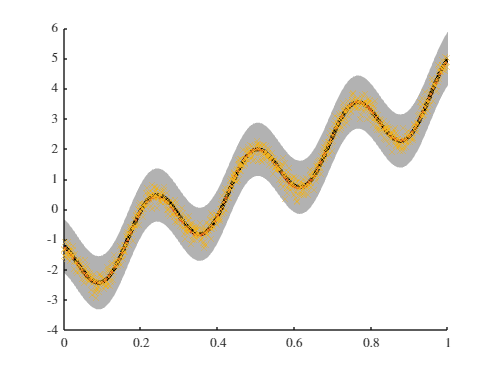

Z1 = Z.condition(x1,y1);

[ys,sig] = Z1.eval(xx);

figure
hold on
utils.plotLineOut(Z1,0.5,1)
plot(xx,yy,'.')
plot(x1,y1,'x')

tic
[Z2,LL] = Z1.train();
toc

Elapsed time is 3.604535 seconds.


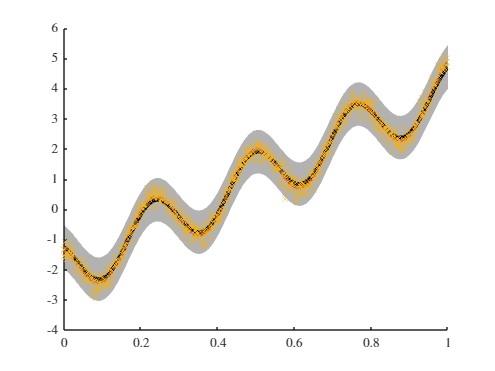

figure
hold on
utils.plotLineOut(Z2,0.5,1)
plot(xx,yy,'.')
plot(x1,y1,'x')

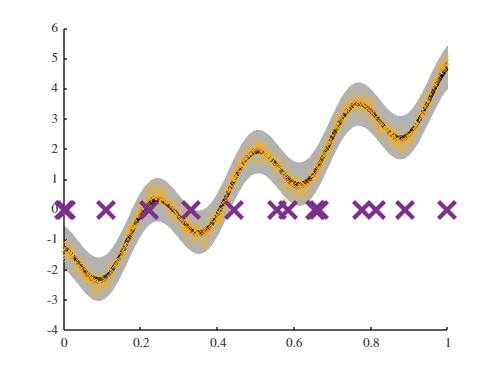

for i = 1:5
    %xn = bads(@(x) Z2.newXuDiff(x),rand(1),0,1,0,1,[],opts);
    %opts = optimoptions('fmincon','Display','off');
    %xn = fmincon(@(x) Z2.newXuDiff(x),rand(),[],[],[],[],0,1,[],opts);
    xn = Z2.newXuDiff();
    Z2 = Z2.addInducingPoints(xn);
end

figure
hold on
utils.plotLineOut(Z2,0.5,1)
plot(xx,yy,'.')
plot(x1,y1,'x')
plot(Z2.Xu,0*Z2.Xu,'x','MarkerSize',18,'LineWidth',3)

tic
[Z3,LL] = Z2.train();
toc

Elapsed time is 3.581001 seconds.


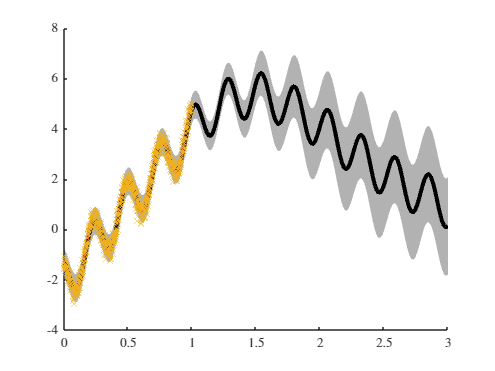

figure
hold on
utils.plotLineOut(Z3,0.5,1,'ub',3)
plot(xx,yy,'.')
plot(x1,y1,'x')